# Project1-1 BearingDiagnosis

2025/12/20

Joungbin Choi

22200757

Industrial AI

### Data Load and Preprocessing

clear; close all; clc;

try
    addpath("../IAIA/Library/");
catch
    warning('라이브러리 경로를 찾을 수 없어 스크립트 하단의 내부 함수를 사용합니다.');
end

% 데이터 로드
load("C:\Users\joung\source\repos\IAIA\HGU_bearing_dataset_v1.mat");
dataStruct = HGU_bearing_dataset_v1;
fs = dataStruct.sampling_freq; 
fr = dataStruct.rotating_freq; 
trainset = dataStruct.trainset;
testset  = dataStruct.testset;
class_names = {'N1','N2','I1','I2','O1','O2','B1','B2'};

% 고장 주파수 계산
NB = 13; D1 = 37.05; D2 = 24.95; 
D = (D1+D2)/2; d = (D1-D2)/2;
BPFO = (NB/2)*fr*(1 - (d/D));       % 외부 결함
BPFI = (NB/2)*fr*(1 + (d/D));       % 내부 결함
BSF  = (D/(2*d))*fr*(1 - (d/D)^2);  % 볼 결함
FTF  = (fr/2)*(1 - (d/D));          % 케이지 결함
fault_freqs = [BPFO, BPFI, BSF, FTF];


### Feature Extraction

% Train Feature
Xtr = []; Ytr = [];
for c = 1:numel(class_names)
    Xc = trainset.(class_names{c});
    for i = 1:size(Xc,2)
        x = Xc(:,i);
        feat = [
            get_statistical_feature(x, fs), ...              % Time + Freq (18개)
            get_envelope_features(x, fs, fault_freqs), ...   % Envelope (12개)
            get_wavelet_features(x)                          % Wavelet (16개)
        ];
        Xtr = [Xtr; feat];
        Ytr = [Ytr; c];
    end
end

% Test Feature
Xte = []; Yte = [];
for c = 1:numel(class_names)
    Xc = testset.(class_names{c});
    for i = 1:size(Xc,2)
        x = Xc(:,i);
        feat = [
            get_statistical_feature(x, fs), ...
            get_envelope_features(x, fs, fault_freqs), ...
            get_wavelet_features(x)
        ];
        Xte = [Xte; feat];
        Yte = [Yte; c];
    end
end

% 정규화
mu = mean(Xtr);
sigma = std(Xtr);
sigma(sigma==0) = 1; 

Xtr_norm = (Xtr - mu) ./ sigma;
Xte_norm = (Xte - mu) ./ sigma;

Ytr_cat = categorical(Ytr, 1:8, class_names);
Yte_cat = categorical(Yte, 1:8, class_names);

% Feature 나누기
num_stat = 18; num_env = 12; num_wav = 16;

idx_stat = 1:num_stat;
idx_env  = (num_stat+1):(num_stat+num_env);
idx_wav  = (num_stat+num_env+1):(num_stat+num_env+num_wav);
idx_all  = 1:(num_stat+num_env+num_wav);

feature_split = {
    'Statistical',     idx_stat;
    'Envelope',        idx_env;
    'Wavelet',         idx_wav;
    'ALL Combined',    idx_all
};

results = table('Size',[0,3], 'VariableTypes',{'string','string','double'}, ...
    'VariableNames',{'FeatureSet','Model','Accuracy'});


### Classification

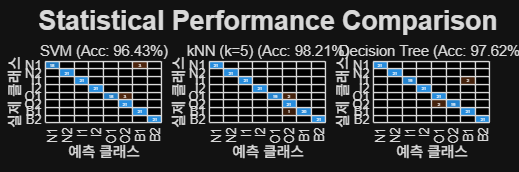

[Statistical] -> SVM: 96.43%, kNN: 98.21%, Tree: 97.62%


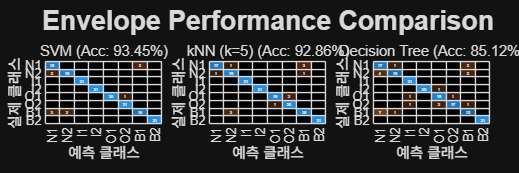

[Envelope] -> SVM: 93.45%, kNN: 92.86%, Tree: 85.12%


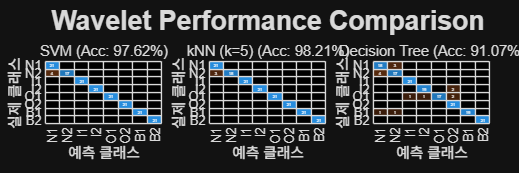

[Wavelet] -> SVM: 97.62%, kNN: 98.21%, Tree: 91.07%


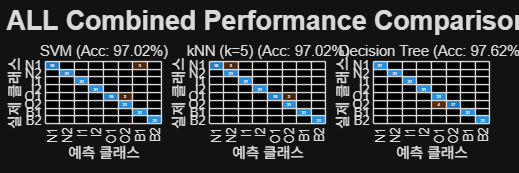

[ALL Combined] -> SVM: 97.02%, kNN: 97.02%, Tree: 97.62%


% 모델 학습 및 비교 (SVM, kNN, Decision Tree)
for s = 1:size(feature_split, 1)
    s_name = feature_split{s,1};
    s_idx  = feature_split{s,2};
    
    X_tr_sub = Xtr_norm(:, s_idx);
    X_te_sub = Xte_norm(:, s_idx);
    
    fig = figure('Name', s_name, 'Position', [100, 100, 1200, 400]);
    t = tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(t, [s_name, ' Performance Comparison'], 'FontSize', 16, 'FontWeight', 'bold');
    
    % SVM
    t_svm = templateSVM('KernelFunction','gaussian', 'KernelScale','auto', 'Standardize',false);
    mdl_svm = fitcecoc(X_tr_sub, Ytr_cat, 'Learners', t_svm);
    Ypred_svm = predict(mdl_svm, X_te_sub);
    acc_svm = mean(Ypred_svm == Yte_cat) * 100;
    
    nexttile; confusionchart(Yte_cat, Ypred_svm);
    title(sprintf('SVM (Acc: %.2f%%)', acc_svm));
    results = [results; {s_name, 'SVM', acc_svm}];
    
    % kNN, k=5
    mdl_knn = fitcknn(X_tr_sub, Ytr_cat, 'NumNeighbors', 5, 'Standardize', false);
    Ypred_knn = predict(mdl_knn, X_te_sub);
    acc_knn = mean(Ypred_knn == Yte_cat) * 100;
    
    nexttile; confusionchart(Yte_cat, Ypred_knn);
    title(sprintf('kNN (k=5) (Acc: %.2f%%)', acc_knn));
    results = [results; {s_name, 'kNN', acc_knn}];
    
    % Decision Tree
    mdl_tree = fitctree(X_tr_sub, Ytr_cat, 'MinLeafSize', 5);
    Ypred_tree = predict(mdl_tree, X_te_sub);
    acc_tree = mean(Ypred_tree == Yte_cat) * 100;
    
    nexttile; confusionchart(Yte_cat, Ypred_tree);
    title(sprintf('Decision Tree (Acc: %.2f%%)', acc_tree));
    results = [results; {s_name, 'Decision Tree', acc_tree}];
    
    fprintf('[%s] -> SVM: %.2f%%, kNN: %.2f%%, Tree: %.2f%%\n', ...
        s_name, acc_svm, acc_knn, acc_tree);
end

### Result Table

% 최종 결과
featureNames = ["Statistical", "Envelope", "Wavelet", "Full"];
modelNames = ["kNN", "SVM", "Decision Tree"];

accMat = zeros(numel(featureNames), numel(modelNames));

for i = 1:numel(featureNames)
    for j = 1:numel(modelNames)
        idx = results.FeatureSet == feature_split{i,1} & ...
              results.Model == modelNames(j);
        accMat(i,j) = results.Accuracy(idx);
    end
end

ResultTable = table( ...
    accMat(:,1), accMat(:,2), accMat(:,3), ...
    'VariableNames', {'KNN','SVM','DecisionTree'}, ...
    'RowNames', featureNames ...
);

disp(ResultTable);

                    KNN       SVM      DecisionTree
                   ______    ______    ____________

    Statistical    98.214    96.429       97.619   
    Envelope       92.857    93.452       85.119   
    Wavelet        98.214    97.619       91.071   
    Full           97.024    97.024       97.619   



cv = cvpartition(Ytr_cat, 'KFold', 5);

% kNN 기반 SFS 평가 함수
knn_fun = @(XT, YT, Xt, Yt) ...
    mean(predict(fitcknn(XT, YT, ...
        'NumNeighbors',5,'Standardize',false), Xt) ~= Yt);

opts = statset('Display','iter');

[selected_idx, history] = sequentialfs( ...
    knn_fun, Xtr_norm, Ytr_cat, ...
    'cv', cv, ...
    'options', opts);

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 7번 열 추가, 기준값 0.000732788
2단계, 12번 열 추가, 기준값 0.000536541
3단계, 1번 열 추가, 기준값 0.000309728
4단계, 39번 열 추가, 기준값 9.28075e-05
5단계, 10번 열 추가, 기준값 4.11986e-05
6단계, 2번 열 추가, 기준값 3.0862e-05
최종적으로 포함된 열: 1 2 7 10 12 39 



selected_features = find(selected_idx);
fprintf('SFS selected %d features\n', numel(selected_features));

SFS selected 6 features


Xtr_sfs = Xtr_norm(:, selected_idx);
Xte_sfs = Xte_norm(:, selected_idx);

t_svm = templateSVM('KernelFunction','gaussian', ...
                    'KernelScale','auto', 'Standardize',false);

mdl_svm_sfs = fitcecoc(Xtr_sfs, Ytr_cat, 'Learners', t_svm);
Ypred_svm_sfs = predict(mdl_svm_sfs, Xte_sfs);

acc_svm_sfs = mean(Ypred_svm_sfs == Yte_cat) * 100;
fprintf('SFS + SVM Accuracy: %.2f%%\n', acc_svm_sfs);

SFS + SVM Accuracy: 98.81%



mdl_knn_sfs = fitcknn(Xtr_sfs, Ytr_cat, ...
    'NumNeighbors',5,'Standardize',false);

Ypred_knn_sfs = predict(mdl_knn_sfs, Xte_sfs);
acc_knn_sfs = mean(Ypred_knn_sfs == Yte_cat) * 100;

fprintf('SFS + kNN Accuracy: %.2f%%\n', acc_knn_sfs);

SFS + kNN Accuracy: 98.81%



mdl_tree_sfs = fitctree(Xtr_sfs, Ytr_cat, 'MinLeafSize', 5);

Ypred_tree_sfs = predict(mdl_tree_sfs, Xte_sfs);
acc_tree_sfs = mean(Ypred_tree_sfs == Yte_cat) * 100;

fprintf('SFS + Decision Tree Accuracy: %.2f%%\n', acc_tree_sfs);

SFS + Decision Tree Accuracy: 94.64%



SFS_ResultTable = table( ...
    [acc_knn_sfs; acc_svm_sfs; acc_tree_sfs], ...
    'VariableNames', {'Accuracy'}, ...
    'RowNames', {'kNN + SFS','SVM + SFS','DecisionTree + SFS'} ...
);

disp(SFS_ResultTable);

                          Accuracy
                          ________

    kNN + SFS               98.81 
    SVM + SFS               98.81 
    DecisionTree + SFS     94.643 



### Feature Visualization

Statistical Feature Graph

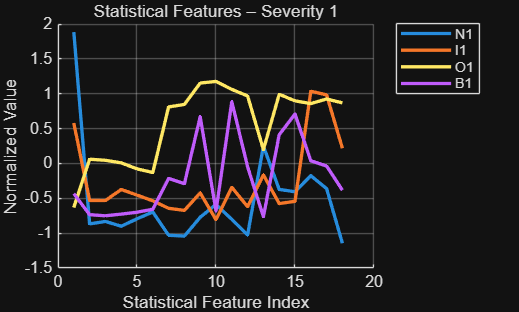

cls_sev1 = [1 3 5 7];   % N1 I1 O1 B1
cls_sev2 = [2 4 6 8];   % N2 I2 O2 B2
labels_sev1 = {'N1','I1','O1','B1'};
labels_sev2 = {'N2','I2','O2','B2'};

% Statistical Features
figure
hold on; grid on;
for k = 1:numel(cls_sev1)
    c = cls_sev1(k);
    plot(mean(Xtr_norm(Ytr==c, idx_stat),1),'LineWidth',2);
end
xlabel('Statistical Feature Index');
ylabel('Normalized Value');
title('Statistical Features – Severity 1');
legend(labels_sev1,'Location','bestoutside');

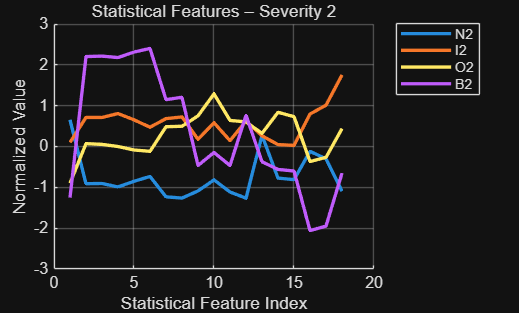


figure
hold on; grid on;
for k = 1:numel(cls_sev2)
    c = cls_sev2(k);
    plot(mean(Xtr_norm(Ytr==c, idx_stat),1),'LineWidth',2);
end
xlabel('Statistical Feature Index');
ylabel('Normalized Value');
title('Statistical Features – Severity 2');
legend(labels_sev2,'Location','bestoutside');

Envelope Feature Power Spectrum Visualization

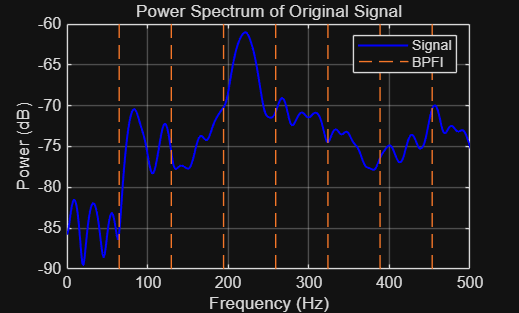

target_class = 'I2';
x = dataStruct.trainset.(target_class)(:, 1);

x = double(x); 
x = x - mean(x);

x_filt = highpass(x, 50, fs); 

env = abs(hilbert(x_filt)); 
env = env - mean(env);

[ori_p, ori_f] = pspectrum(x, fs);

figure
plot(ori_f, 10*log10(ori_p), 'b', 'LineWidth', 1.2); hold on;
helperPlotCombs(10, BPFI);
title('Power Spectrum of Original Signal');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
xlim([0, 500]); 
legend('Signal', 'BPFI')
grid on;

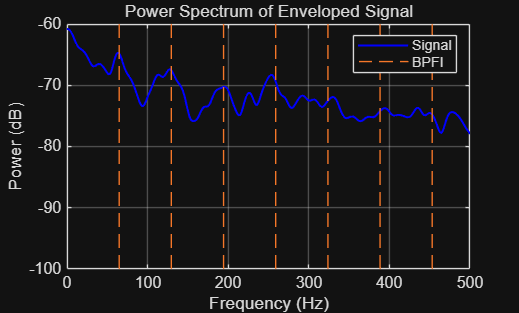


[p, f] = pspectrum(env, fs);

figure
plot(f, 10*log10(p), 'b', 'LineWidth', 1.2); hold on;
helperPlotCombs(10, BPFI)
title('Power Spectrum of Enveloped Signal');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
xlim([0, 500]); 
legend('Signal', 'BPFI')
grid on;

Wavelet Heatmap

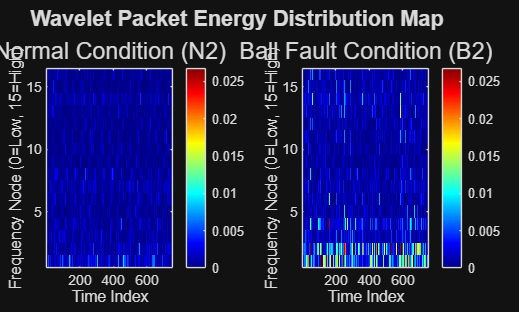

xO_n2 = dataStruct.trainset.N2(:, 1);
xO_b2 = dataStruct.trainset.B2(:, 1);

% Wavelet Packet 분해 설정 (Level 4, db4)
level = 4;
wname = 'db4';
num_nodes = 2^level; 

wp_n2 = wpdec(double(xO_n2), level, wname);
map_n2 = [];
for n = 0:num_nodes-1
    c = wpcoef(wp_n2, [level n]);
    map_n2 = [map_n2; abs(c(:))'];
end

wp_b2 = wpdec(double(xO_b2), level, wname);
map_b2 = [];
for n = 0:num_nodes-1
    c = wpcoef(wp_b2, [level n]);
    map_b2 = [map_b2; abs(c(:))'];
end

figure
t = tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

max_val = max(map_b2(:)) * 0.6; 

nexttile;
imagesc(map_n2);
colormap(jet); 
colorbar;
clim([0, max_val]); 
title('Normal Condition (N2)', 'FontSize', 14);
ylabel('Frequency Node (0=Low, 15=High)');
xlabel('Time Index');
set(gca, 'YDir', 'normal'); 

nexttile;
imagesc(map_b2);
colormap(jet); 
colorbar;
clim([0, max_val]);
title('Ball Fault Condition (B2)', 'FontSize', 14);
ylabel('Frequency Node (0=Low, 15=High)');
xlabel('Time Index');
set(gca, 'YDir', 'normal');

sgtitle('Wavelet Packet Energy Distribution Map', 'FontWeight', 'bold');

### 함수

% Time+Frequency Feature
function feat = get_statistical_feature(x, fs)
    T_table = timeFeatures_student(x); 
    feat_time = table2array(T_table); 
    
    % Frequency Domain Statistics
    L = length(x);
    P1 = getFFT_student(x, L);
    N = length(P1);
    f = (0:N-1) * (fs / (2*(N-1)));
    A = P1(:)';
    
    sum_A = sum(A); if sum_A == 0, sum_A = 1; end
    
    fc   = sum(f .* A) / sum_A;                 
    rmsf = sqrt(sum((f.^2).*A) / sum_A);        
    rvf  = sqrt(sum((f - fc).^2 .* A) / sum_A); 
    
    feat = [feat_time, fc, rmsf, rvf];
end

% Envelope Feature
function feat_vec = get_envelope_features(x, fs, freqs)
    x = double(x); x = x - mean(x);
    x_filt = highpass(x, 50, fs); 
    env = abs(hilbert(x_filt)); env = env - mean(env);
    L = length(env);
    P1 = abs(fft(env)/L); P1 = P1(1:floor(L/2)+1);
    f = (0:floor(L/2))*(fs/L);
    feat_vec = [];
    for df = freqs
        for k = 1:3
            target = df * k;
            bw = 3.0; 
            idx = (f >= target-bw) & (f <= target+bw);
            if any(idx), val = max(P1(idx)); else, val = 0; end
            feat_vec = [feat_vec, val];
        end
    end
end

% Wavelet feature
function feat_wav = get_wavelet_features(x)
    x = double(x);
    level = 4;
    wp = wpdec(x, level, 'db4');
    feat_wav = zeros(1, 2^level);
    for n = 0:(2^level - 1)
        c = wpcoef(wp, [level n]);
        feat_wav(n+1) = sum(c.^2);
    end
    total_E = sum(feat_wav);
    if total_E > 0, feat_wav = feat_wav / total_E; end
end